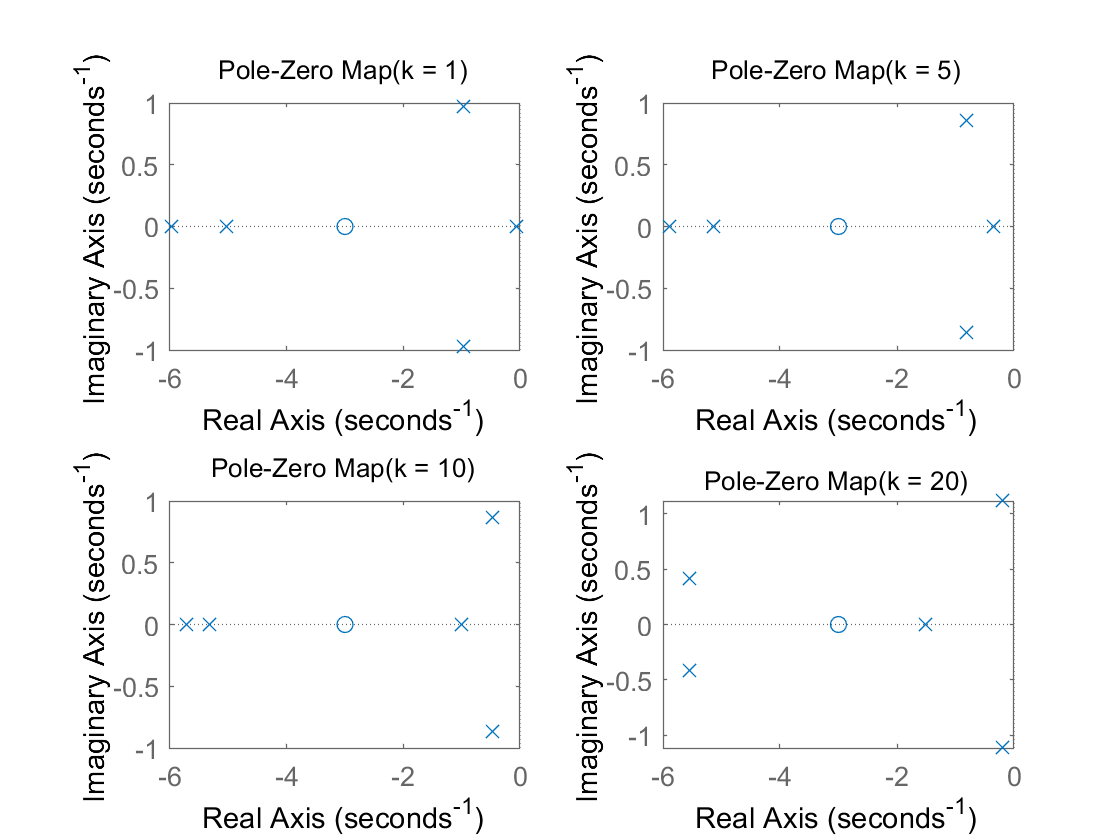

 
k = [1,5,10,20];
z = -3;
p = [0,-5,-6];
s1 = zpk(z,p,k(1));
s2 = zpk(z,p,k(2));
s3 = zpk(z,p,k(3));
s4 = zpk(z,p,k(4));


num = 1;
den = [1,2,2];
s = tf(num,den);

sy1 = s1*s;
sy2 = s2*s;
sy3 = s3*s;
sy4 = s4*s;

sys1 = feedback(sy1,1,-1);
sys2 = feedback(sy2,1,-1);
sys3 = feedback(sy3,1,-1);
sys4 = feedback(sy4,1,-1);

syst1 = tf(sys1);
syst2 = tf(sys2);
syst3 = tf(sys3);
syst4 = tf(sys4);

figure
subplot(2,2,1)
pzmap(syst1)
title("Pole-Zero Map(k = 1)")
xlabel("Real Axis")
ylabel("Imaginary Axis")


subplot(2,2,2)
pzmap(syst2)
title("Pole-Zero Map(k = 5)")
xlabel("Real Axis")
ylabel("Imaginary Axis")


subplot(2,2,3)
pzmap(syst3)
title("Pole-Zero Map(k = 10)")
xlabel("Real Axis")
ylabel("Imaginary Axis")


subplot(2,2,4)
pzmap(syst4)
title("Pole-Zero Map(k = 20)")
xlabel("Real Axis")
ylabel("Imaginary Axis")